**1**

clc; clear; close all;
sympref('HeavisideAtOrigin', 1);

b = [ 0 0 0 0.3 -0.19 ]

b =          0         0         0    0.3000   -0.1900


a = [ 1 -1.5 0.56 ]

a =     1.0000   -1.5000    0.5600


**1.1**

function result = getZSum(coef, z)
arguments (Input)
	coef
	z
end

arguments (Output)
	result
end

result = 0;

for k = 1:length(coef)
	result = result + coef(k) * z .^ (-(k - 1));
end

end

syms z n
Gz = symfun(getZSum(b, z) / getZSum(a, z), z);
pretty(Gz);

   3       19
 ----- - ------
     3        4
 10 z    100 z
---------------
  14     3
----- - --- + 1
    2   2 z
25 z



**1.2**

Gz = simplify(Gz);
pretty(Gz);

        30 z - 19
------------------------
 2      2
z  (50 z  - 75 z + 28) 2



[num, den] = numden(Gz);
numCoef = sym2poly(num)

numCoef =     30   -19


denCoef = sym2poly(den)

denCoef =    100  -150    56     0     0


zeros = roots(numCoef)

zeros = 0.6333

poles = roots(denCoef)

poles =          0
         0
    0.8000
    0.7000


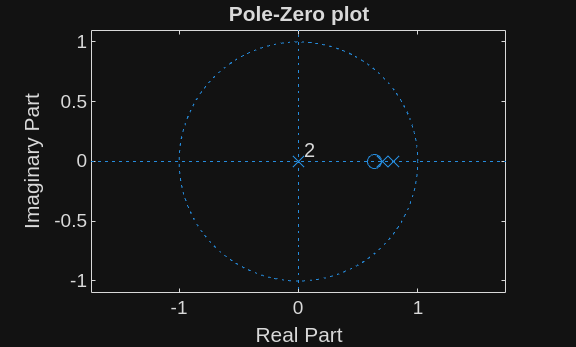


figure;
zplane(zeros, poles);
title("Pole-Zero plot");

**1.3**

if all(abs(poles) < 1)
	disp("O sistema e estavel");
else
	disp("O sistema e instavel");
end

O sistema e estavel


**1.4**

G0 = Gz(1)

$$G0 = \frac{11}{6}$$

G0_dc = ddcgain(b, a)

G0_dc = 1.8333

**1.5**

hn = iztrans(Gz, z, n)

$$hn = \frac{125\,{\left(\frac{4}{5}\right)}^{n}}{128}-\frac{19\,\delta_{n-2,0}}{56}-\frac{585\,\delta_{n-1,0}}{1568}-\frac{200\,{\left(\frac{7}{10}\right)}^{n}}{343}-\frac{17275\,\delta_{n,0}}{43904}$$

delay = length(b(b == 0));
[r, p, i] = residuez(b(b ~= 0), a);
GzRes = 0;
for i = 1:length(r)
	GzRes = GzRes + r(i) / (1 - p(i) * z .^ (-1));
end
for i = 0:length(p) - length(r)
	GzRes = GzRes + i(i + 1) * z .^ (-i);
end
GzRes = GzRes * z .^ (-delay);
hnRes = iztrans(GzRes, z, n)

$$hnRes = \frac{125\,{\left(\frac{4}{5}\right)}^{n}}{128}-\frac{19\,\delta_{n-2,0}}{56}-\frac{585\,\delta_{n-1,0}}{1568}-\frac{200\,{\left(\frac{7}{10}\right)}^{n}}{343}-\frac{17275\,\delta_{n,0}}{43904}$$

**1.6**

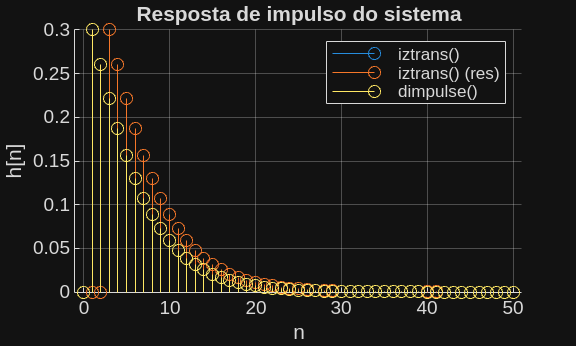

nVals = 0:50;
hnVals = double(subs(hn, n, nVals));
hnResVals = double(subs(hnRes, n, nVals));

figure;
hold on;
stem(nVals, hnVals);
stem(nVals, hnResVals);
stem(nVals, dimpulse(b, a, length(nVals)));
hold off;
title("Resposta de impulso do sistema");
xlabel("n");
ylabel("h[n]");
legend("iztrans()", "iztrans() (res)", "dimpulse()");
grid on;

**1.7**

if ~isinf(sum(abs(hnVals)))
	disp("O sistema e estavel");
else
	disp("O sistema e instavel");
end

O sistema e estavel



disp("O sistema e causal, pois h[n] = 0, n < 0");

O sistema e causal, pois h[n] = 0, n < 0


**1.8**

X1z = ztrans(heaviside(n), n, z)

$$X1z = \frac{1}{z-1}+1$$

Y1z = simplify(Gz * X1z)

$$Y1z(z) = \frac{\left(30\,z-19\right)\,\left(\frac{1}{z-1}+1\right)}{2\,z^{2}\,\left(50\,z^{2}-75\,z+28\right)}$$

y1n = iztrans(Y1z, z, n);
pretty(y1n)

                                  / 4 \n       /  7 \n
                              125 | - |    200 | -- |
19 kroneckerDelta(n - 1, 0)       \ 5 /        \ 10 /    1117 kroneckerDelta(n, 0)   11
--------------------------- - ---------- + ----------- + ------------------------- + --
             56                   32           147                  1568              6



**1.9**

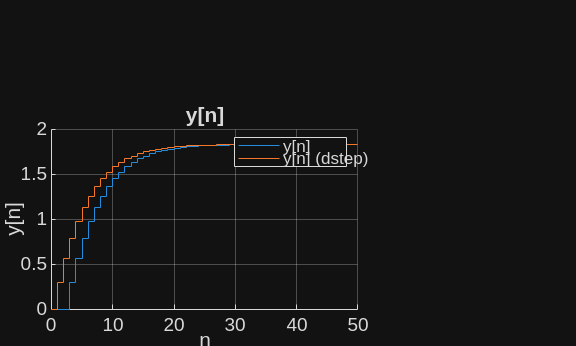

y1nVals = double(subs(y1n, n, nVals));

figure;
hold on;
stairs(nVals, y1nVals);
stairs(nVals, dstep(b, a, length(nVals)));
hold off;
title("y[n]");
xlabel("n");
ylabel("y[n]");
legend("y[n]", "y[n] (dstep)");
grid on;

**1.10**

y1nLim = limit(y1n, n, inf)

$$y1nLim = \frac{11}{6}$$

Y1zLim = limit((1 - z .^ (-1)) * Y1z, z, 1)

$$Y1zLim = \frac{11}{6}$$

G0

$$G0 = \frac{11}{6}$$

**1.11**

x2n = symfun(3 * (heaviside(n - 2) - heaviside(n - 10)), n)

$$x2n(n) = 3\,\mathrm{heaviside}\left(n-2\right)-3\,\mathrm{heaviside}\left(n-10\right)$$

x2nVals = double(subs(x2n, n, nVals));
y2nDlsimVals = dlsim(b, a, x2nVals);
X2z = ztrans(x2n, n, z);
Y2z = simplify(Gz * X2z);
y2n = iztrans(Y2z, z, n)

$$y2n = \frac{375740838010120875\,\delta_{n-1,0}}{16587018934943744}+\frac{5089008627339225\,\delta_{n-2,0}}{592393533390848}+\frac{4239149314515\,\delta_{n-3,0}}{21156911906816}-\frac{3407908877679\,\delta_{n-4,0}}{755603996672}-\frac{161307239493\,\delta_{n-5,0}}{26985857024}-\frac{5889191031\,\delta_{n-6,0}}{963780608}-\frac{188914077\,\delta_{n-7,0}}{34420736}-\frac{5508159\,\delta_{n-8,0}}{1229312}-\frac{145653\,\delta_{n-9,0}}{43904}-\frac{3351\,\delta_{n-10,0}}{1568}-\frac{57\,\delta_{n-11,0}}{56}+\frac{3047709375\,{\left(\frac{4}{5}\right)}^{n}}{33554432}-\frac{1884703980000\,{\left(\frac{7}{10}\right)}^{n}}{13841287201}+\frac{21055950772484150625\,\delta_{n,0}}{464436530178424832}$$

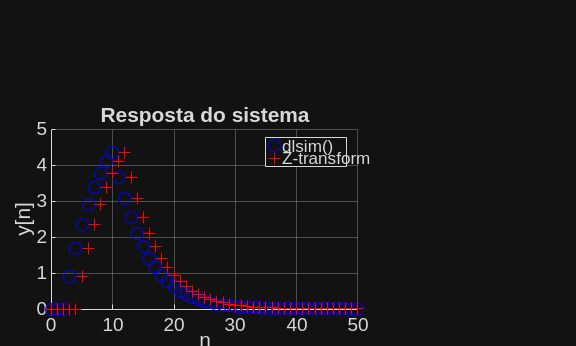

y2nZtransVals = double(subs(y2n, n, nVals));

figure;
hold on;
plot(nVals, y2nDlsimVals, 'ob');
plot(nVals, y2nZtransVals, '+r');
hold off;
title("Resposta do sistema");
xlabel("n");
ylabel("y[n]");
legend("dlsim()", "Z-transform");
grid on;

**1.12**

syms om
omVals = linspace(0, pi, 1000);
Hom = symfun(simplify(subs(Gz, z, exp(1j * om))), om)

$$Hom(om) = \frac{{\mathrm{e}}^{-2\,\mathrm{om}\,\mathrm{i}}\,\left(30\,{\mathrm{e}}^{\mathrm{om}\,\mathrm{i}}-19\right)}{2\,\left(28+50\,{\mathrm{e}}^{2\,\mathrm{om}\,\mathrm{i}}-75\,{\mathrm{e}}^{\mathrm{om}\,\mathrm{i}}\right)}$$

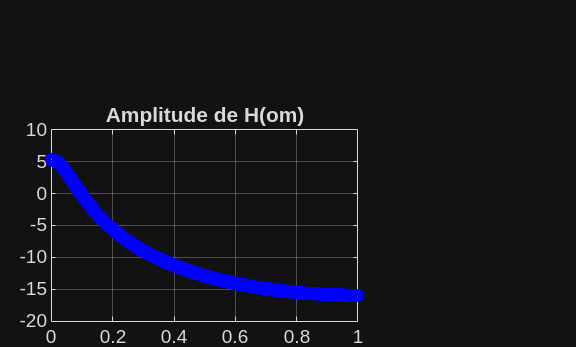

absHom = symfun(simplify(abs(Hom(om))), om);
angleHom = symfun(simplify(angle(Hom(om))), om);
absHomDb = symfun(20 * log10(absHom(om)), om);
angleHomDVals = unwrap(double(angleHom(omVals))) * (180 / pi);

figure;
plot(omVals / pi, double(absHomDb(omVals)), "ob");
title("Amplitude de H(om)");
grid on;

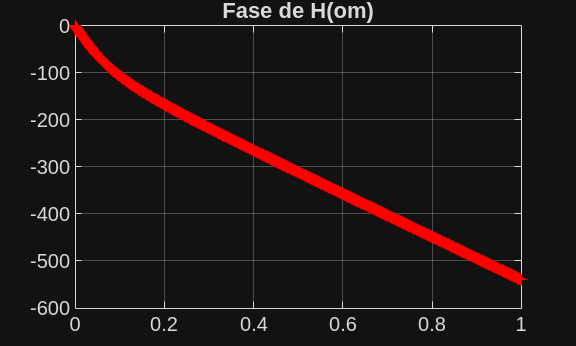


figure;
plot(omVals / pi, angleHomDVals, "+r");
title("Fase de H(om)");
grid on;

**1.13**

Hom(0)

$$ans = \frac{11}{6}$$

**1.14**

om0 = 0.1 * pi

om0 = 0.3142

x3n = symfun(2 * sin(om0 * n), n)

$$x3n(n) = 2\,\sin\left(\frac{\pi \,n}{10}\right)$$

y3n = symfun(2 * absHom(om0) * sin(om0 * n + angleHom(om0)), n)

$$y3n(n) = \begin{array}{l} \frac{\sin\left(\mathrm{atan}\left(\frac{\frac{\sigma_{2}\,\sigma_{5}}{\sigma_{3}}-\frac{\sigma_{1}\,\sigma_{4}}{\sigma_{3}}}{\frac{\sigma_{1}\,\sigma_{5}}{\sigma_{3}}+\frac{\sigma_{2}\,\sigma_{4}}{\sigma_{3}}}\right)-\frac{\pi \,n}{10}\right)\,\sqrt{{\left(\frac{15\,\sqrt{5}}{2}-\frac{15}{2}\right)}^{2}+{\left(\frac{15\,\sqrt{2}\,\sqrt{\sqrt{5}+5}}{2}-19\right)}^{2}}}{\sqrt{\sigma_{3}}}\\ \mathrm{where}\\ \sigma_{1}=\left(\frac{\sqrt{5}}{4}+\frac{1}{4}\right)\,\left(\frac{15\,\sqrt{5}}{2}-\frac{15}{2}\right)-\frac{\sqrt{2}\,\left(\frac{15\,\sqrt{2}\,\sqrt{\sqrt{5}+5}}{2}-19\right)\,\sqrt{5-\sqrt{5}}}{4}\\ \sigma_{2}=\left(\frac{\sqrt{5}}{4}+\frac{1}{4}\right)\,\left(\frac{15\,\sqrt{2}\,\sqrt{\sqrt{5}+5}}{2}-19\right)+\frac{\sqrt{2}\,\left(\frac{15\,\sqrt{5}}{2}-\frac{15}{2}\right)\,\sqrt{5-\sqrt{5}}}{4}\\ \sigma_{3}={\sigma_{4}}^{2}+{\sigma_{5}}^{2}\\ \sigma_{4}=\frac{25\,\sqrt{5}}{2}-\frac{75\,\sqrt{2}\,\sqrt{\sqrt{5}+5}}{4}+\frac{81}{2}\\ \sigma_{5}=\frac{25\,\sqrt{2}\,\sqrt{5-\sqrt{5}}}{2}-\frac{75\,\sqrt{5}}{4}+\frac{75}{4} \end{array}$$

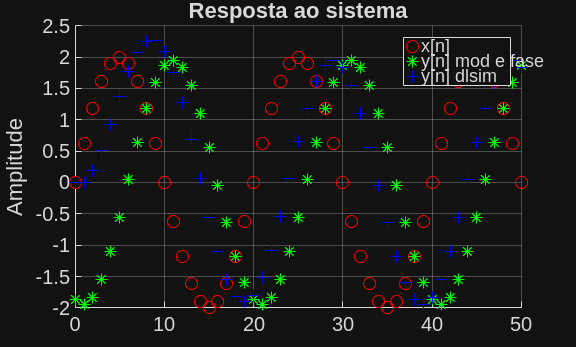

y3nDslim = dlsim(b, a, double(x3n(nVals)));

figure;
hold on;
plot(nVals, double(x3n(nVals)), "or");
plot(nVals, double(y3n(nVals)), "*g");
plot(nVals, y3nDslim, "+b");
hold off;
title("Resposta ao sistema");
xlabel("n");
ylabel("Amplitude");
legend("x[n]", "y[n] mod e fase", "y[n] dlsim");
grid on;